# Ejercicio 3 (2 puntos). Diagramas de bloque en MATLAB. 

### MATLAB incluye una serie de funciones que permiten crear cualquier diagrama de bloques creando sistemas vinculados a entradas y salidas y conectando dichos sistemas. Las principales funciones que pueden emplearse para ello son: connect y sumblk. A modo de ejemplo, suponga el siguiente diagrama de bloques del cual nos interesa obtener las funciones de transferencia:

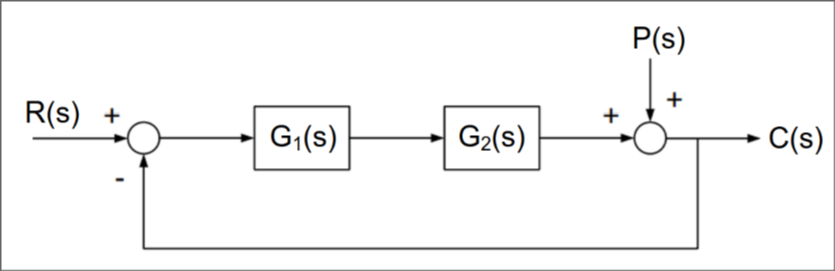

### Utiliza la ayuda de MATLAB para conocer la sintaxis y argumentos de ambos comandos. Implementa el código que configura el diagrama de bloques de la figura y obtiene las funciones de transferencia de interés, C(s)/R(s) y C(s)/P(s), donde G1(s)=1/(s+2) y G2(s)=2/(s+1).

Primero definimos las funciones de transferencia

Como nos los dan en forma factorizada, usamos la función zpk

G1 = zpk([],-2,1)

G1 =
 
    1
  -----
  (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


G2 = zpk([],-1,2)

G2 =
 
    2
  -----
  (s+1)
 
Continuous-time zero/pole/gain model.
Model Properties


Gp=tf(21,1) % En nuestro caso decidimos darle un valor de 21 a la perturbancia

Gp =
 
  2100
 
Static gain.
Model Properties


Como el dibujo no lo indica, le asignaremos nombres a la entrada y salida de cada bloque

G1.InputName = "e";
G1.OutputName = "u1";
G2.InputName = "u1";
G2.OutputName = "u2";
Gp.InputName = "u3";
Gp.OutputName = "p";

Luego representamos los puntos de suma con la función sumblk (a la cual le pasamos las entradas y salidas previamente definidas)

S1 = sumblk('c = u2 + p')

S1 =
 
  From input "u2" to output "c":
  1
 
  From input "p" to output "c":
  1
 
Static gain.
Model Properties


S2 = sumblk('e = r - c')

S2 =
 
  From input "r" to output "e":
  1
 
  From input "c" to output "e":
  -1
 
Static gain.
Model Properties


Ya una vez definidos los bloques y los puntos de suma, podemos usar la función connect para definir el diagrama de bloques.

BD = connect(G1,G2 ,S1,S2,{'r','p'},{'c'})

BD =
 
  A = 
       x1  x2
   x1  -2  -1
   x2   2  -1
 
  B = 
        r   p
   x1   1  -1
   x2   0   0
 
  C = 
      x1  x2
   c   0   1
 
  D = 
      r  p
   c  0  1
 
Continuous-time state-space model.


tf(BD) %Utilizamos tf para ver el resultado en forma polinómica

ans =
 
  From input "r" to output "c":
        2
  -------------
  s^2 + 3 s + 4
 
  From input "p" to output "c":
  s^2 + 3 s + 2
  -------------
  s^2 + 3 s + 4
 
Continuous-time transfer function.
Model Properties


En este caso podemos que ambos tienen el  mismo denominador y por ende son compatibles/equivalentes